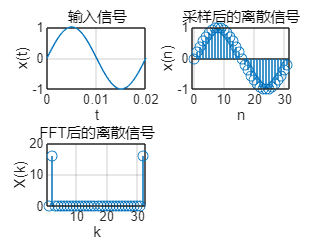

clear;clc;

%输入
f=input('信号频率F/hz=');
N=input('采样点数N=');
T=input('采样时间间隔T/s=');
m=input('初始相位=');
flag=input('是否补零（1为yes/0为no）=');

%生成离散信号
pi=3.1415926;
x=sin(2*pi*f*(0:N-1)*T+m); 


%补零
if flag==1 
   n=input('补零个数=');
   x=[x,zeros(1,n)];   
   N=N+n;
end

%FFT
nx=bin2dec(fliplr(dec2bin(0:N-1)))+1;
y=x(nx);
for i=1:N
   A(i)=y(i);
end

for M = 1:log2(N)
    L = 2^(M-1);
    for J = 0:L-1

        for k=(J+1):2^M:N
            W=exp(-1j*2*pi*J/(N/2^(log2(N)-M)));
            R=A(k)+A(k+L)*W;
            Q=A(k)-A(k+L)*W;
            A(k)=R;
            A(k+L)=Q;
        end
    end
end

%图像分析
%输入信号
subplot(2,2,1);
t=0:0.0000001:N*T;
plot(t,sin(2*pi*f*t+m));
title('输入信号');   
xlabel('t');
ylabel('x(t)');
grid on;
%采样后的离散信号
subplot(2,2,2);
d=0:N-1;
stem(d,x);     
title('采样后的离散信号');
xlabel('n');
ylabel('x(n)');
grid on;
%程序运算出的FFT
subplot(2,2,3);
X=abs(A(d+1));%输出X(k）的值
stem(d+1,abs(A(d+1)));     
title('FFT后的离散信号');
xlabel('k');
ylabel('X(k)');
grid on;